clear all
d1=load("E:\MTP2\SPI weekly\SPI_1month_08_18.mat");

spi=d1.SPI;

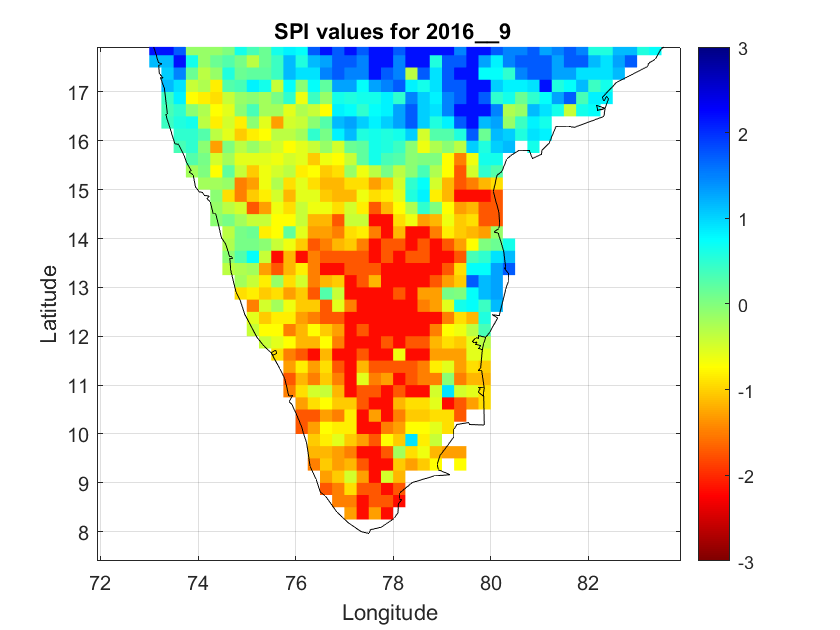

for i = 105
    data=spi(:,:,i);
    date=spi(1,1,i);
    month=rem(date,100);
    year=floor(date/100);
    st_date=int2str(year)+"__"+int2str(month);
    lat=data(2:130,1,1);
    lon=data(1,2:136,1)';
    crop1=(data(2:130,2:136,1));
    f=figure(1);
    slp=pcolor(lon,lat,crop1);
    slp.EdgeColor='none';
    xlabel('Longitude'); % Labelling x axis
    ylabel('Latitude'); % Labelling y axis
    title(' SPI values for '+st_date); % Putting title to the figure
    colormap(flipud(jet)) % Setting a color scheme
    hcb1=colorbar; % Showing the scheme on a scale
    caxis([-3 3])
    %title(hcb1,'(in m3/m3)') % Titling a colorbar
    grid on % Showing grid lines
    hold on % Starting a new plot on same figure retaining the former
    geoshow("E:\MTP2\precipitation\shapefile\india.shp",'FaceAlpha',0); % Plotting shapefile of India - you should have a .shp shapefile
    saveas(f,"E:\MTP2\images\spi spatial plots\"+st_date+".png");
    

%     clear figure(1);
%     clear f;
%     close;
end